# 回帰 (基礎)

Regression: Basics

**おすすめの予習**

[MATLAB 入門](https://jp.mathworks.com/learn/tutorials/matlab-onramp.html) – MATLABの基本的な使い方についての２時間の無料チュートリアル

## 回帰とは？

回帰とは、一つの従属変数 (dependent variable) (y) と１つ以上の独立変数 (independent variable) (x) の関係を推定する、一連の統計学的手法を指します。言い換えると、対象となる（従属）変数を他の（独立）変数によってモデル化する方法である、ということです。回帰はデータから予想や予測を行うために広く使われています。

### 線形回帰 (Linear regression)

単純な例として、一つの従属変数と一つの独立変数がある場合について考えましょう。この場合、単純な線形回帰、つまり

直線を$y\;=a_0 +a_1 x$でモデルして２つの変数の関係を定義します。

２つの変数の関係を、式$y\;=a_0 +a_1 x$で定義する直線でモデル化します。

load linearData.mat x y

*課題: ****Run****ボタンを押して、下のスライダーによって定義された傾き(slope)と切片(intercept)を持つ直線を作りましょう。*

a1 =-0.3;
a0 =-0.7;
 

plotFit(x,y,[a1 a0]);

  **やってみよう**

- *スライダーを使って傾き (slope) (*$a_1$*) と切片 (intercept) (*$a_0$*) を定義する変数を設定し、データを予測するために様々な直線を作ってみましょう*

- *データを説明するのに最もよい直線となるようなa1とa0を見つけましょう。うまくいくような複数の係数 (coefficient) が複数存在しうることに注意します*

 **考えてみよう**

- 良い係数を見つけるのは簡単でしたか？

- 直線がデータに対して当てはまりがよい (good fit) かどうかについて、どうやって判断しましたか？

- x=5のとき、yの値を予測できますか？

disp("Use the dropdown to reveal a likely solution")

後のセクションでは、適合度 (Goodness of fit) を決める方法を学びます。

### 非線形回帰 (Nonlinear Regression)

もう少し複雑な例について考えてみましょう。例えば$y\;=a_0 +a_1 x+a_2 x^2 +a_3 x^3 +a_4 x^4 +\;\ldotp \ldotp \ldotp$のような形で表せる、単一の独立変数についての非線形回帰を行いたいとします。

load nonlinearData.mat x y

***課題****: 編集フィールドで-3から3の間で係数 (coefficient values) を設定しましょう。*$a_4$と$a_3$については既に設定してあります。**Runボタン**をクリックしてプロットしてみましょう。

a4 = 0.2;
a3 = 0.5;
a2 = 2;
a1 = 1;
a0 = -0.2;
 

plotFit(x,y,[a4 a3 a2 a1 a0]);

 **考えてみよう**

- 良い係数を見つけるのはどのくらい簡単、または難しかったですか？

- 直線のデータに対する当てはまりがよい (good fit) とどうやって判断しましたか？

- x=-4のとき、yの値を予測できますか？

disp("Use the dropdown to reveal a likely solution")

### 多変量回帰 (Multivariable Regression)

さらに複雑な問題設定の場合、一つの従属変数に対して複数の独立変数が存在します。この場合、単純な平面の式 (equation of a simple plane) である $y=f\left(x_1 ,x_2 \right)=a*x_1 +b*x_2 +c$ のような形で表せる多変量線形回帰 (multivariable or multiple linear regression) を用います。

load multivariateData.mat x1 x2 y

***課題****: Runボタンをクリックし、以下で定められた係数を持つ平面を描いてみましょう。*

a =-0.7;
b =-0.3;
c =0.4;
 

plotMultiFit(x1,x2,y,[a b c]);

  **やってみよう**

- $x_1 ,x_2 ,y$の関係を表現するような平面になるように、 $a_2$, $a_1$, $a_0$の値をスライダーを使って定義しましょう

- スライダーを使って、$x_1 ,x_2 ,y$の関係をモデル化する、異なる平面を生成するように、 $a_2$, $a_1$, $a_0$の値を設定しましょう

- データを最もうまく説明するような平面になるように$a_2$, $a_1$, $a_0$の係数を決めましょう。これはとても難しいです。Figureウインドウの左上に出てくるRotateやPanなどのプロットツールを使うと、作業がやりやすくなります

 **考えてみよう**

- データを表現するのに最良の係数を見つけるのは、どのくらい簡単、または難しかったですか？

- 選んだ係数が当てはまりがよい (good fit) とどうやって判断しましたか？

disp("Use the dropdown to reveal a likely solution")

## コスト関数 (Cost Function)

上の例題では、あなた自身が曲線のデータへのあてはめを行い、その曲線がどの程度変数間の関係を表すか（おそらく）目で見て判断していました。適合度を評価するより正確な方法として、コスト関数 (cost function)を計算するという方法があります。このコスト関数は、（あてはめられた回帰モデルから）予測されたデータと、実際のデータ（正解データ、 ground truth)との間の誤差を表現します。コスト関数の簡単な例としては、平均二乗誤差 (Mean square error, MSE) があり、以下の式で定義されます: 

 
$$f=\frac{1}{n}\sum_{i=1}^n {\left(Y_i -{\hat{Y} }_i \right)}^2$$


 $Y$は実際に観測された従属変数の値を表します。予則はそれぞれの従属変数の $n$データ点について行われます。$\hat{Y}$はモデル（線形回帰モデルなど）による予測値を表します。

簡単にいうと、MSEは与えられたサンプルデータ点についての二乗予測誤差の平均です。このような良し悪しの指標は、変数の関係を推定するときに最小化すべきコストのして扱うことが可能です。

load linearData2.mat x y

**課題***: 係数*$a_1 ,a_{0\;}$を定め、$y$を予測する線形回帰モデルをフィットさせましょう。より良い係数を見つけるために、MSEを使いましょう。

a1 =-0.5;
a0 =-0.6;
 

yhat = plotFit(x,y,[a1 a0]);
MSE = mean((y-yhat).^2);

text(-2,1,"MSE = " + MSE,"FontSize",14)

MATLABの変数である`y`と`yhat`はそれぞれn点のデータを持つベクトルであり、数式の$Y$ と $\hat{Y}$に相当します。

 **考えてみよう**

- モデルの成績を決めるために使える他のコスト関数はありますか？

## 最急降下法 (Gradient Descent)

最も正確なデータとモデルのあてはめを行うために、誤差、つまり（フィットしたモデルによる）予測値と（正解データである）実際の値との間の差分を最小化したいと思います。上の例では、最良の係数を自分でいろいろあてはめて探してもらいました。最良の係数を見つけ出しコスト関数の値を最小化する体形的なやり方として、最急降下法 (gradient descent) を用います。これは最適化問題 (optimization problem) であるともいえます。

rng(250)
x = -3:0.05:2;
y = (-2*x+0.5) + 0.5*randn(size(x));

***課題:*** ***Run****ボタンをクリックし、最急降下法の仕組みを可視化しましょう。*

learningRate = 0.07;
epochs = 30;
 

[a1,a0,mse] = gradientDescent(x,y,epochs,learningRate);

ここでは係数が２つだけの単純な問題を考えます。MSEとモデル係数$a_0$ , $a_1$の関係を3次元プロットで視覚化しましょう。このプロットは、1つの最小値（赤い点）を持つ谷のようです。私たちがやりたいことは、その最小値に到達することであるというのを覚えておきましょう。勾配降下法では、ある点（例えば上の頂点の1つ）から出発して、谷を下る方向に計算していきます。これは反復ステップ（エポックと呼ばれます）によって行われます。ステップサイズは学習率 (learning rate)と言われる[ハイパーパラメータ](https://www.mathworks.com/support/search.html/videos/applied-machine-learning-part-3-hyperparameter-optimization-1547849445386.html?fq=asset_type_name%3Avideo+category%3Astats%2Fregression-and-anova&page=1)によって決まります。

  **やってみよう**

- *様々な学習率や繰り返し回数*`epochs`を試すためにスライダーを使いましょう。Runボタンを押して最急降下法がどうなるか見てみます

- `learningRate`*を0.01に設定してみましょう*

- *低い学習率に合わせて、*`epochs`*を80に増やします*

- `learningRate`*を0.25, *`epochs`*を30にします*

- `learningRate`*を0.35に増加させましょう*

 **考えてみよう**

- 低い学習率を設定するとどうなりますか？

- 高い学習率を設定するとどうなりますか？

- エポックの数は学習結果にどう影響しますか？

名前が示す通り、この手法ではコスト関数の勾配を計算する必要があります。これらは各係数についての偏微分 (partial derivatives) となります。係数は、各エポックにおいて、現在の値からそれぞれの勾配を差し引いて更新されていきます。MSEコスト関数の場合は、以下のような勾配式になります: 


$$\frac{d\left(f\right)}{da_1 }=\frac{2\alpha }{n}\sum_{i=1}^n X_i \left({\hat{Y} }_i -Y_i \right)$$
                     
$$\frac{d\left(f\right)}{da_0 }=\frac{2\alpha }{n}\sum_{i=1}^n \left({\hat{Y} }_i -Y_i \right)$$


$\alpha$ は学習率を表します。

## 練習問題

#### 負荷の予測

電力網を支えるために必要な電力量は、電力網の**負荷 (load)** と呼ばれ、1日を通して大きく変動します。ニューヨークのダウンタウンにおける送電網の負荷の例を以下に示します。

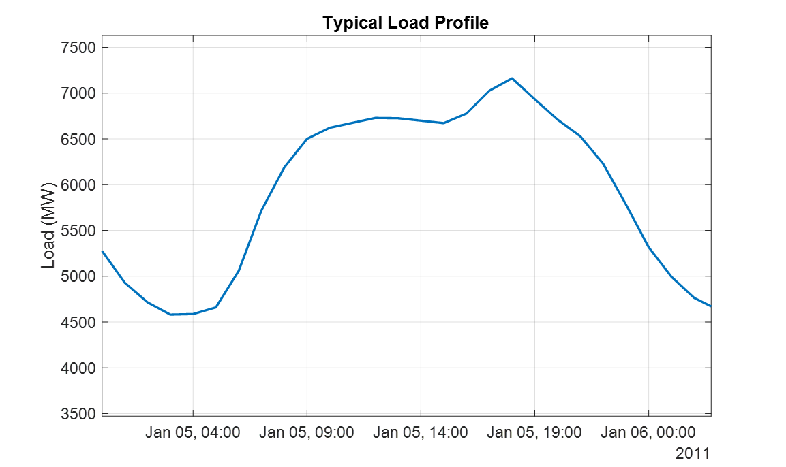

電力負荷の予測を行うことが欠かせない企業もあります。電力会社にとっては、発電所でどれだけの電力を生産する必要があるかを計画することに役立ちます。また、電力売買業者にとっても、今後の市場動向を把握することに役立ちます。

**将来の電力負荷要求を予測できるでしょうか？**

**注意:** この例題のために、外部データを[New York ISO](http://mis.nyiso.com/public/)からダウンロードする必要があります。インターネット接続の条件次第ですが、およそ1-5分程度かかるでしょう。ダウンロードを自動的に行うためのスクリプトがあります。（Optional) 下のコードサンプルを実行して、ダウンロードを行うスクリプトを開くことができます。

** データをダウンロードするために、以下の指示にしたがってから次のセクションに進みましょう**

- *このセクションを実行します*

- *画面が出たら、データを保存するフォルダを選択します。編集ボックスにフォルダが表示されるように、フォルダを明示的に選択してから、****フォルダ選択****ボタンをクリックするようにしてください*

- *選択した場所にすでにデータが存在している場合、このスクリプトはデータをダウンロード**しません**。この動作を変更したい場合、スクリプトを開いてドロップダウンを変更します*

electricityLoadData

まずは、将来の電力負荷を予測するために単純な線形回帰を使いましょう。従属変数には電力負荷、独立変数には時間のみを使います。

***課題:**** 電力データの時間の細かさ (granularity) を選びましょう。****Run****ボタンをクリックし、時間を独立変数とした線形回帰を実行します。*

load nyiso_cleaned.mat nyiso

tt = retime(nyiso,"daily","mean")       % Select granularity of data
 

[fitlm](https://www.mathworks.com/help/stats/fitlm.html)関数が線形回帰モデルをフィットするために使われます。`datetime` 変数を数値に変換して回帰をあてはめます。

mdl = fitlm(datenum(tt.Date),tt.HUDVL);
coeffs = mdl.Coefficients
MSE = mdl.MSE

フィットしたモデルを[plot](https://www.mathworks.com/help/releases/R2020b/stats/linearmodel.plot.html#responsive_offcanvas)して、データの散布図を可視化できます。

plot(mdl)
xticklabels(datestr(xticks))
xtickangle(30)

   **やってみよう**

- *ドロップダウンメニューを使って、負荷データの細かさを選びましょう*

- ***Run****ボタンをクリックして計算された誤差の値を見てみましょう*

   **考えてみよう**

- 誤差の値が最も高く (highest) なるのはどんな時ですか？

- 誤差の値が最も低く (lowest) なるのはどんな時ですか？

- 線形回帰ではどの（時間の）細かさが良いでしょうか？一番良い時間幅というのは、何を意味していますか？

いったんモデルが使えるようになれば、[predict](https://www.mathworks.com/help/stats/linearmodel.predict.html)関数を使って任意の独立変数に対応する従属変数を計算することができます。

predDay = 21
predMonth = 8
predYear =2021
 

predDate = datetime(predYear,predMonth,predDay);
predLoad = predict(mdl,datenum(predDate));

disp("Your model predicts a load of "+predLoad+ "MW for "+ datestr(predDate))

前のセクションでは、粒度が高いデータでは良い予測はできなかったものの、全体的な傾向を予測するために結果を用いることができます。

 **問題*****: ****この結果をもとに、当てはまるものをすべて選びなさい*

**A. Hudson Valleyの電力負荷は、2021年には2020年と比較してきっと増加するだろう。**

increase = false;

**B.** **Hudson Valleyの電力負荷は、2021年には2020年と比較してきっと減少するだろう。**

decrease = false;

if increase & ~decrease disp("Correct"); else disp("Try again") ;end

 **考えてみよう**

- ある時点での電力負荷に影響を与える、他の要因や変数についての心あたりがありますか？

## 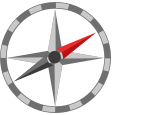追加の練習 (Further Exploration)

#### 短期電力負荷予測のための複数予測因子 (Multiple predictors for short-term electricity load forecast)

お気づきの通り、`Date`が唯一の独立変数であり、時間単位での予測はあまり正確ではありません。

独立変数は、**説明変数** (***explanatory variables***) や**予測変数** (***predictor*** ***variables)***、あるいは単に**予測因子** (***predictors) ***と呼ばれます。独立変数を変えたり、変数を組み合わせたりすることで、データの適合性と予測の精度を高めることが可能です。ここでは、1時間ごとの電力負荷 (kWh) に対する、3つの異なる予測値を生成する関数である`getMultiPredictors`が与えられています。

***課題:**** このセクションを実行し、結果を見てみましょう。*

load nyiso_cleaned.mat nyiso
[hourlyLoad,dates,predictors] = getMultiPredictors(nyiso);

disp(predictors)

線形重回帰 (multiple linear regression) モデルをフィットさせます。

mdl = fitlm(predictors,hourlyLoad);
mdl.Coefficients

このフィットさせたモデルを用いて"Predict" をしましょう; つまり、実際の値と比較するためにモデルをあてはめるということです。

predLoad = predict(mdl,predictors);

実際の負荷の値と予測された負荷の値をプロットします。

figure
plot(dates,hourlyLoad,"o","MarkerSize",4)
hold on 
plot(dates,predLoad,"r")
hold off
legend("Actual","Predicted")
xlabel("Time")
ylabel("Hourly Load (MW)")
title("Electricity Load: Multiple Linear Regression");

細かい時間窓に合わせて図を拡大して見てみるために、下のサンプルコードをこの直前のコードセクションに挿入してみましょう。

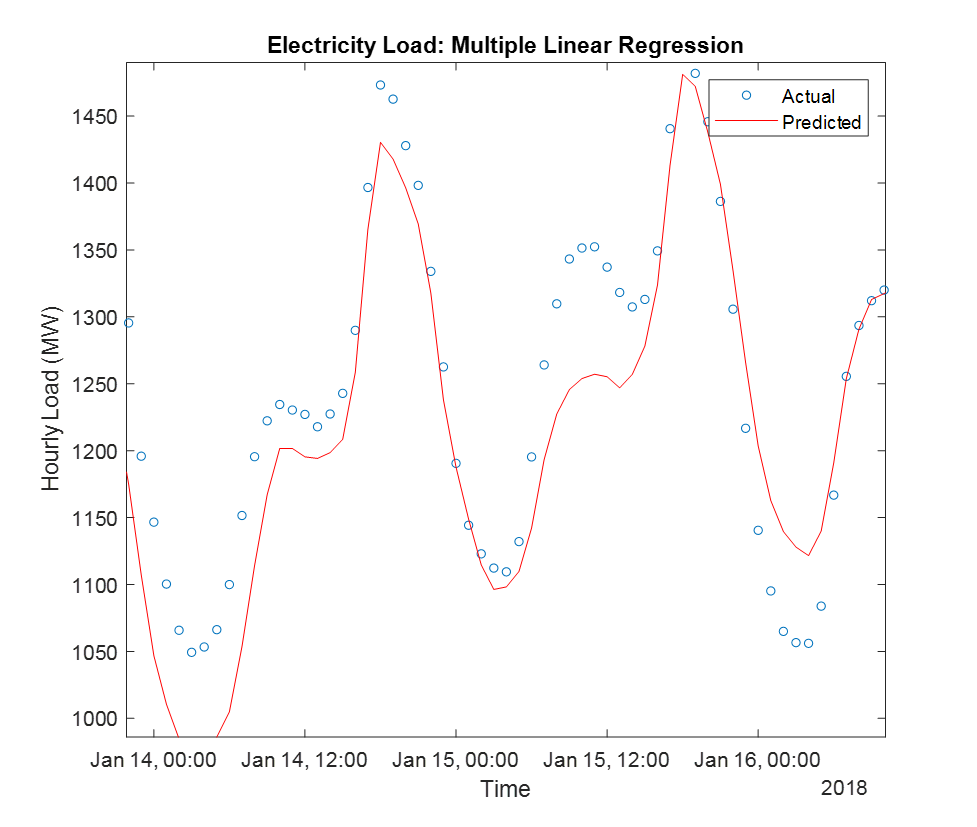

 **考えてみよう**

上に表示された`predictors`変数について見てみましょう。

- 3つの予測因子について、それぞれがどんな物理量を表しているかを見つける手がかりとなるパターンに気付きましたか？**ヒント**：各列を `hourlyLoad`の値と比較しましょう。

- 今回のモデルがどの程度先まで見通せるかについて何かわかりますか？その理由についてはどうでしょうか？

## Helper functions

任意の次数 (degree) の単一変数回帰をプロットする関数

function yhat = plotFit(x,y,A)
powers = length(A)-1:-1:0;
X = x'.^powers;
yhat = A*X';
 
% Plot
figure("Position",[0 0 600 400],"Color",[0.9 0.9 0.9]);
plot(x,y,"o");
xlim([min(x)-0.5,max(x)+0.5]);
ylim([min(y)-0.5,max(y)+0.5]);
hold on
fplot(@(x)A*(x'.^powers)',"LineWidth",1.5);
hold off
title("y = " + join(A + ["*x^{"+string(powers(1:end-1))+"}",""] ," + "),"Interpreter","tex");
xlabel("x")
ylabel("y or f(x)")

end

係数についてフィットした平面をプロットする関数

function yhat = plotMultiFit(x1,x2,y,coeffs)

[a,b,c] = deal(coeffs(1),coeffs(2),coeffs(3));
yhat = a.*x1 + b.*x2 + c;

% Plot
figure("Position",[0 0 600 400],"Color", [0.9 0.9 0.9]);
scatter3(x1,x2,y);
xlim([min(x1)-0.1,max(x1)+0.1]);
ylim([min(x2)-0.1,max(x2)+0.1]);
zlim([min(y)-0.1,max(y)+0.1]);
[X1,X2] = meshgrid(xlim,ylim);
hold on
surf(X1,X2,a.*X1 + b.*X2 + c,"FaceAlpha", 0.4,"FaceColor",[1 0.5 0.5],"EdgeColor","none");
hold off
title("y = " + a + "x_{1}  +  " + b + "x_{2}  +  " + c);
view([-150 20])
xlabel('x_{1}'), ylabel('x_{2}'), zlabel("y")

end

線形回帰について、平均二乗誤差 (mean-squared error cost) で最急降下法 (gradient descent) を実行して可視化する関数

function [a1,a0,mse] = gradientDescent(x,y,epochs,learningRate)

bgGray = [0.9 0.9 0.9];
figure("Position",[0 0 800 400],"Color",bgGray);

[M,B] = meshgrid(-10:0.1:10,-10:0.1:10);
cost = arrayfun(@(m,b)costFunc(m,b,x,y),M,B);

% Initialize loop   
a1 = 7;                       % initial slope value
a0 = 7;                       % initial intercept value
n = length(x);                % total number of data points      
mse = costFunc(a1,a0,x,y);    % compute initial MSE
r = logspace(-0.5,0,epochs);  % red color intensities for the plots

% Plot three different visualizations
T = tiledlayout(2,2,"TileSpacing","compact","Padding","compact");
    
% Plot 1- surface
nexttile(T,1)
surf(M,B,cost,"EdgeColor","none")
hold on
plot3(a1,a0,mse,"*","Color",[0 0 0]);
hold off
set(gca, "Color",bgGray)
colormap(parula(30))
view([-16 33])
xlabel("a1"), ylabel("a0"), zlabel("Cost (MSE)")

% Plot 2- contour
nexttile(T,2)
contour(M,B,cost,30,"LineWidth",2)
hold on
plot(a1,a0,"*","Color",[0 0 0],"MarkerSize",8)
hold off
set(gca, "Color",bgGray)
xlabel("a1"), ylabel("a0")

% Plot 3- line fit
title(T,"Gradient descent")
nexttile(T,[1,2])
plot(x,y,"o")
set(gca, "Color",bgGray)
hold on
fitLine = plot(xlim,a1.*xlim+a0,"-","LineWidth",1.5,"Color",[0 0 0]);
hold off
ylim([-10,10]), xlabel("x"), ylabel("y")


for step=1:epochs
    
    % Compute gradient descent
    pause(0.02)
    yhat = a1*x + a0;
    diff = yhat - y;
    da1 = learningRate * sum(diff .* x) * 2 / n;
    da0 = learningRate * sum(diff) * 2 / n;
    a1 = a1 - da1;
    a0 = a0 - da0;
    mse = costFunc(a1,a0,x,y);
    
    % Plot new iteration data over the existing plots
    nexttile(T,1)
    hold on
    plot3(a1,a0,mse,"*","Color",[r(step) 0 0]);
    hold off
    
    nexttile(T,2)
    hold on
    plot(a1,a0,"*","Color",[r(step) 0 0],"MarkerSize",8)
    hold off
    
    nexttile(T,3)
    fitLine.YData = a1*xlim+a0;
    fitLine.Color = [r(step) 0 0];
    title("a1 = "+a1 + ", a0 = "+a0, "MSE = "+mse)
  
end
end

直線あてはめ (linear fit) のために平均二乗誤差を計算する関数

function mse = costFunc(m,b,x,y)
yhat = m*x+b;
mse = sum((yhat-y).^2)/length(x);
end

時間ごとの（電力）負荷について複数の予測変数を作成する

function [hourlyLoad,dates,predictors] = getMultiPredictors(nyiso)
tt = retime(nyiso,"hourly","mean");
pred = tt.HUDVL;
N = [7 24 168];
predictors = [[nan(N(1),1); pred(1:end-N(1))],[nan(N(2),1); pred(1:end-N(2))],[nan(N(3),1); pred(1:end-N(3))]];
hourlyLoad = tt.HUDVL;
dates = tt.Date;
end